% Create a Datastore
% Instructions are in the task pane to the left. Complete and submit each task one at a time.
% This code displays the images in the current folder and imports AlexNet.
ls *.jpg


test01.jpg  test02.jpg  



net = alexnet;

% Task 1
% Create datastore
imds =imageDatastore('test*.jpg')

imds =   ImageDatastore - 属性:

                       Files: {
                              'E:\MATLAB_Workspace\CNN\test01.jpg';
                              'E:\MATLAB_Workspace\CNN\test02.jpg'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage



% Task 2
% Extract file names
fname = imds.Files

fname = 2×1 cell 数组
    {'E:\MATLAB_Workspace\CNN\test01.jpg'}
    {'E:\MATLAB_Workspace\CNN\test02.jpg'}



% Task 3
% Read an image
img =readimage(imds,1)

img = 227×227×3 uint8 数组
img(:,:,1) =

   247   248   251   252   253   253   254   254   252   252   251   251   252   251   251   252   253   254   253   250   248   244   242   239   240   239   235   234   234   235   237   238   238   238   239   239   240   241   244   246   246   248   248   247   248   244   241   238   242   239   234   231   227   220   216   213   211   208   206   207   208   210   214   216   221   223   223   223   225   229   229   228   226   225   223   221   219   216   213   212   208   207   205   204   203   202   201   201   199   197   197   198   199   199   200   201   199   202   208   211   212   212   212   212   210   209   206   204   202   201   200   200   200   200   200   201   200   202   211   217   223   225   231   232   231   230   228   228   233   233   233   235   236   235   230   226   226   220   217   212   207   201   198   198   200   200   198   199   198   197   195   196   196   195   196   196   199   200   202   202 


% Task 4
% Classify images
preds =classify(net,imds);

% % 补充：
[pred1,scores] = classify(net,imds)

pred1 = 2×1 categorical 数组
     conch 
     sandbar 


scores = 2×1000 single 矩阵
    0.0000    0.0000    0.0000    0.0001    0.0000    0.0223    0.0016    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0001    0.0000    0.0012    0.0000    0.0000    0.0000    0.0005    0.0022    0.0000    0.0002    0.0000    0.0003    0.0009    0.0007    0.0005    0.0004    0.0000    0.0005    0.0000    0.0007    0.0004    0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

b=max(scores,[],2)

b = 2×1 single 列向量
    0.3479
    0.4968


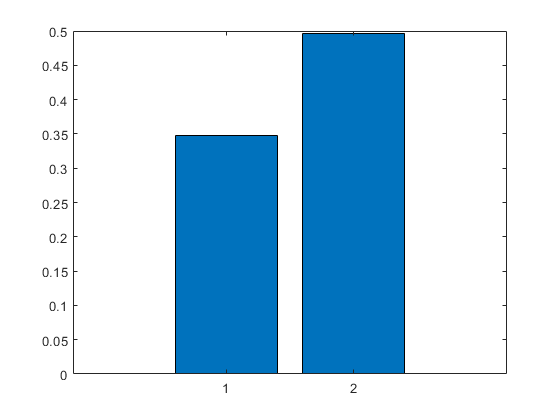

bar(b)